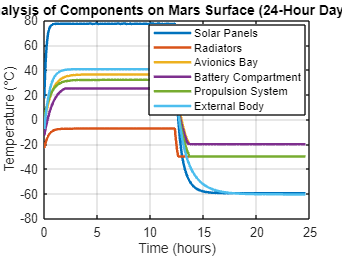

clear; clc;

% Constants
sBoltzmann = 5.670e-8;
SolarFlux_Mars = 589;   
Albedo_Mars = 0.25;   
T_mars = 210;          
T_space = 2.7;        

day_duration = 12.3 * 3600;  
night_duration = 12.3 * 3600;
edl_duration = 9 * 3600;

nodes = {'Solar Panels', 'Radiators', 'Avionics Bay', 'Battery Compartment', 'Propulsion System', 'External Body'};
Area = [2.0; 0.9; 0.8; 0.5; 1.0; 1.5];
absorb = [0.8; 0.2; 0.3; 0.3; 0.4; 0.5];
emissivity = [0.8; 0.9; 0.6; 0.7; 0.8; 0.85];

power = [5; 5; 10; 5; 8; 0];

massNode = [10; 5; 8; 6; 12; 15]; 
c_p = 900;  
C = massNode * c_p; 

% Updated Operational and Survival ranges (K)
op_range = [123.15 373.15;   % Solar Panels (-150 to 100)
            243.15 313.15;   % Radiators (-30 to 40)
            263.15 323.15;   % Avionics Bay (-10 to 50)
            273.15 288.15;   % Battery (0 to 15)
            253.15 313.15;   % Propulsion System (-20 to 40)
            153.15 378.15];  % External Body (thermal sensors) (-120 to 105)

survival_range = [93.15 393.15;    % Solar Panels (-180 to 120)
                  243.15 323.15;   % Radiators (-30 to 50)
                  253.15 333.15;   % Avionics Bay (-20 to 60)
                  253.15 298.15;   % Battery (-20 to 25)
                  243.15 323.15;   % Propulsion System (-30 to 50)
                  133.15 393.15];  % External Body (-140 to 120)

% initial temp (no power)
T_initial = [290, 250, 270, 260, 275, 265];  

% active TCS
kapton_patch_heaters = [5; 0; 3; 4; 0; 3];
radioisotope_heaters = [0; 0; 4; 4; 0; 0];
ricor_cryocoolers     = [1; 1; 2; 0; 1; 4];
thermal_sensors       = [1; 1; 1; 1; 1; 0];

power = power + kapton_patch_heaters + radioisotope_heaters + ricor_cryocoolers + thermal_sensors;

Q_absorb_day = Area .* absorb .* SolarFlux_Mars; 
Q_reflect_day = Area .* absorb .* SolarFlux_Mars * Albedo_Mars; 
Q_planetary_day = Area .* emissivity .* sBoltzmann .* T_mars^4;

Q_planetary_night = Area .* emissivity .* sBoltzmann .* T_mars^4; 
Q_radiative_loss = Area .* emissivity .* sBoltzmann .* T_space^4;

thermalBalanceDay = @(t, T) ((Q_absorb_day + Q_reflect_day + Q_planetary_day + power) - ...
                             (Area .* emissivity .* sBoltzmann .* (T.^4))) ./ C;

thermalBalanceNight = @(t, T) ((Q_planetary_night + power) - ...
                               (Area .* emissivity .* sBoltzmann .* (T.^4) + Q_radiative_loss)) ./ C;

t_full = 0; 
T_full = T_initial;

T_current = T_initial;

[t_day, T_day] = ode45(@(t, T) reshape(thermalBalanceDay(t, T), [], 1), ...
                       [0, day_duration], T_current);
T_current = T_day(end, :);

[t_night, T_night] = ode45(@(t, T) reshape(thermalBalanceNight(t, T), [], 1), ...
                           [0, night_duration], T_current);

T_combined = [T_day; T_night];

for i = 1:length(nodes)
    T_combined(:, i) = max(min(T_combined(:, i), survival_range(i,2)), survival_range(i,1));
end

T_Celsius = T_combined - 273.15;
t_full = [t_day; t_day(end) + t_night];
t_full_hours = t_full / 3600; 

figure;
plot(t_full_hours, T_Celsius, 'LineWidth', 2); 
xlabel('Time (hours)');
ylabel('Temperature (°C)'); 
legend(nodes, 'Location', 'Best');
title('Thermal Analysis of Components on Mars Surface (24-Hour Day-Night Cycle)');
grid on;


% Constraint check after clamping
for i = 1:length(nodes)
    Tmin = min(T_combined(:, i));
    Tmax = max(T_combined(:, i));

    if Tmin < survival_range(i,1) || Tmax > survival_range(i,2)
        fprintf('WARNING: %s out of SURVIVAL range (%.2f°C to %.2f°C), Range: %.2f°C to %.2f°C\n', ...
            nodes{i}, survival_range(i,1)-273.15, survival_range(i,2)-273.15, Tmin-273.15, Tmax-273.15);
    elseif Tmin < op_range(i,1) || Tmax > op_range(i,2)
        fprintf('ALERT: %s out of OPERATIONAL range (%.2f°C to %.2f°C), Range: %.2f°C to %.2f°C\n', ...
            nodes{i}, op_range(i,1)-273.15, op_range(i,2)-273.15, Tmin-273.15, Tmax-273.15);
    end
end

ALERT: Avionics Bay out of OPERATIONAL range (-10.00°C to 50.00°C), Range: -20.00°C to 36.32°C
ALERT: Battery Compartment out of OPERATIONAL range (0.00°C to 15.00°C), Range: -20.00°C to 25.00°C
ALERT: Propulsion System out of OPERATIONAL range (-20.00°C to 40.00°C), Range: -30.00°C to 31.89°C


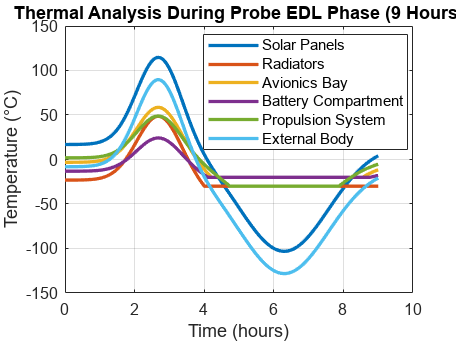


%% EDL Phase (Entry, Descent, Landing)

T_edl_profile = zeros(floor(edl_duration)+1, length(nodes));
t_edl = linspace(0, edl_duration, size(T_edl_profile,1));

for i = 1:length(nodes)
    Tmax = min(survival_range(i,2), T_initial(i) + 100);
    Tmin = max(survival_range(i,1), T_initial(i) - 20);
    t_norm = t_edl / edl_duration;
    T_profile = T_initial(i) + (Tmax - T_initial(i)) * exp(-((t_norm - 0.3)/0.1).^2) ...
                - (Tmax - Tmin) * exp(-((t_norm - 0.7)/0.2).^2);
    T_edl_profile(:, i) = max(min(T_profile, survival_range(i,2)), survival_range(i,1));
end

T_edl_C = T_edl_profile - 273.15;
t_edl_hr = t_edl / 3600;

figure;
plot(t_edl_hr, T_edl_C, 'LineWidth', 2);
xlabel('Time (hours)');
ylabel('Temperature (°C)');
legend(nodes, 'Location', 'Best');
title('Thermal Analysis During Probe EDL Phase (9 Hours)');
grid on;


for i = 1:length(nodes)
    Tmin = min(T_edl_profile(:, i));
    Tmax = max(T_edl_profile(:, i));

    if Tmin < survival_range(i,1) || Tmax > survival_range(i,2)
        fprintf('WARNING (EDL): %s out of SURVIVAL range (%.2f°C to %.2f°C), Range: %.2f°C to %.2f°C\n', ...
            nodes{i}, survival_range(i,1)-273.15, survival_range(i,2)-273.15, Tmin-273.15, Tmax-273.15);
    elseif Tmin < op_range(i,1) || Tmax > op_range(i,2)
        fprintf('ALERT (EDL): %s out of OPERATIONAL range (%.2f°C to %.2f°C), Range: %.2f°C to %.2f°C\n', ...
            nodes{i}, op_range(i,1)-273.15, op_range(i,2)-273.15, Tmin-273.15, Tmax-273.15);
    end
end

ALERT (EDL): Solar Panels out of OPERATIONAL range (-150.00°C to 100.00°C), Range: -103.15°C to 114.70°C
ALERT (EDL): Radiators out of OPERATIONAL range (-30.00°C to 40.00°C), Range: -30.00°C to 48.56°C
ALERT (EDL): Avionics Bay out of OPERATIONAL range (-10.00°C to 50.00°C), Range: -20.00°C to 58.57°C
ALERT (EDL): Battery Compartment out of OPERATIONAL range (0.00°C to 15.00°C), Range: -20.00°C to 24.19°C
ALERT (EDL): Propulsion System out of OPERATIONAL range (-20.00°C to 40.00°C), Range: -30.00°C to 48.78°C
ALERT (EDL): External Body out of OPERATIONAL range (-120.00°C to 105.00°C), Range: -128.15°C to 89.70°C
